clc
clear
file_num = 4;
root_dir = "C:\Users\olive\OneDrive - University of Surrey\individual project\data";
testdate = "26_04_22";
freq = 1/333;

### Qualsis import

path = root_dir + "/" + testdate + "/qualsis_data/*Ollie*.mat";
file_names = dir(path)

file_names = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


current_file = file_names(file_num);
data = load(strcat(current_file.folder, '\', current_file.name));
fnames = fieldnames(data);
data = data.(fnames{1});

trajectories = data.Trajectories.Unidentified.Data;
qualsis_time = (1:1:data.Frames)/data.FrameRate;

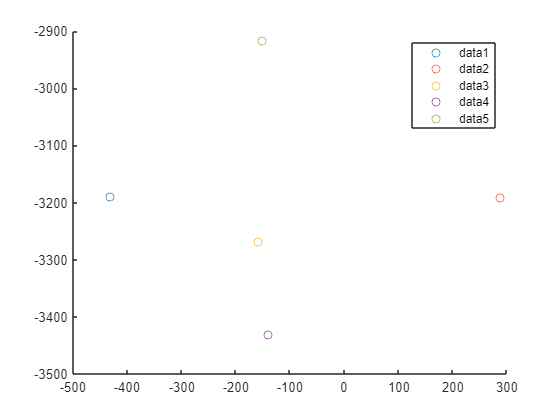

first_instance =1;
clf
hold on
scatter3(trajectories(1,1,first_instance), trajectories(1,2,first_instance), trajectories(1,3,first_instance))
scatter3(trajectories(2,1,first_instance), trajectories(2,2,first_instance), trajectories(2,3,first_instance))
scatter3(trajectories(3,1,first_instance), trajectories(3,2,first_instance), trajectories(3,3,first_instance))
scatter3(trajectories(4,1,first_instance), trajectories(4,2,first_instance), trajectories(4,3,first_instance))
scatter3(trajectories(5,1,first_instance), trajectories(5,2,first_instance), trajectories(5,3,first_instance))
legend
hold off

nose = 5;
tail = 4;
left = 1;
right =2;
mid = 3;

point_order = [nose,tail,left,right,mid];


% interpolate
rebase_time = @(x,f) freq:freq:1/f*length(x);
rebase_qualsis = @(x) interp1(1/120:1/120:(1/120*length(x)), x, rebase_time(x,120));
qualsis_data = [];
num_points = 5;
for point_store = 1:num_points*3
    point = floor((point_store-1)/3) + 1;
    axis = mod(point_store - 1, 3) + 1;
    qualsis_data(:, point_store) = rebase_qualsis(squeeze(trajectories(point_order(point),axis,:)));
end

### UAV import

folder = root_dir + "/" + testdate + "/uav_data/*.csv";

files = dir(folder);
display(files)

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



file_name = files(file_num).folder + "/" + files(file_num).name;
% file = importdata(file_name,',');
% uav_data = file.data(file.data(:,1) < 2000000, :);

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "gx", "gy", "gz", "ax", "ay", "az", "ign"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
uav_data = readtable(file_name, opts);

%interpolate
rebase_uav = @(x) interp1(uav_data{:,1}./1e6, x, rebase_time(x,333));
uav_data_interp = [];
for col = 2:7
    uav_data_interp(:, col-1) = rebase_uav(uav_data{:,col});
end

### Combine & Export

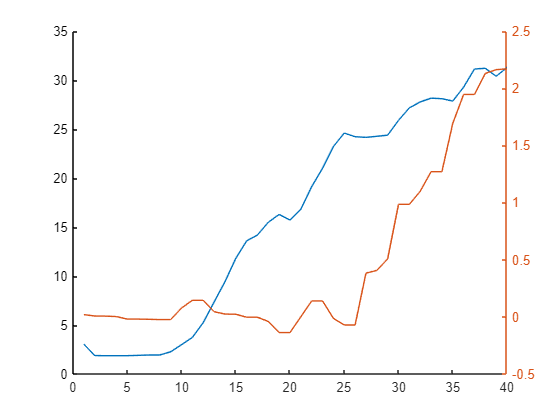

scale = 40;
qualsis_point = 3;
fine = -15;
coarse = 160;
ultra_coarse = 5440;
tune = coarse + fine + ultra_coarse;
clf
xlim([0,scale])
hold("on")
plot(uav_data_interp(:,5))
q = qualsis_data(:, qualsis_point);
yyaxis right
plot(diff(q(tune:end,:)))
hold("off")

final = [];
for qual_i = 1:num_points*3
    final(:,qual_i) = qualsis_data(tune:length(uav_data_interp(:,1)) - 1 + tune, qual_i);
end
for uav_i = 1:6
    final(:,num_points*3+uav_i) = uav_data_interp(:,uav_i);
end

writematrix(final, file_num + "_complete_data.csv")